### Plotting Fig.S1

### Process the FID and fit it to extract J

The fitting function is 

$g(t) \equiv \exp \left(-\frac{a^2 t^2}{2}\right) \frac{\sin b t}{b t}$, where $J=\frac{\sqrt{a^2+b^2 / 3}}{3}$. Therefore, we can fit with 

$g(t) \equiv \exp \left(-\frac{(9J^2-b^2/3) t^2}{2}\right) \frac{\sin b t}{b t}$ to directly get estimation of $J$

Code last modified by Yuchen Li, 2023-9-20

Note: Experimentally we utilize the solid echo to obtain the Free induction decay (FID). Therefore, we vary the value of the echo time and see how it effects the shape of FID.

clc;clear

ExpNum_seq=[1:70];%70 curves of FID in total
echo_time_seq=[50:5:80]; %The echo time is varied from 50 us to 80 us
num_seq=1:length(echo_time_seq); 

repeat=1:10; %For every value of echo time, the FID is repetitively sampled 10 times
J1_seq=zeros(length(repeat),length(num_seq));
J1_uncer_seq=zeros(length(repeat),length(num_seq));

load fid_all.mat; %The rew FID sampled from the spectrometer, including both the real and imaginary parts.
load 'Induction time t.mat' %The sampling time during the FID
fid=[]; %The range of FID used for fitting, of which the first point is the maximal of the real part of FID
for r=1:10
    ii=1;
    for seq_num=num_seq
    % for seq_num=3
        ExpNum=ExpNum_seq((r-1)*7+seq_num);

        RealFid=real(fid_all(:,ExpNum));
        ImagFid=imag(fid_all(:,ExpNum));

        %%Display the raw FID, including both the Real and Imaginary parts
        figure(1)
        plot(t*1e3,RealFid',t*1e3,ImagFid','linewidth',0.8)
        xlabel('Induction time (ms)')
        ylabel('FID')
        legend('Real part', 'Imaginary part','interpreter','latex','box','off')
        fontsize(gcf,10,"points")
        fontname(gcf,'Times New Roman')
        set(gcf,'unit','centimeters','position',[10,10,10,3.5]);

        %
        L=1500;                     %Choose the range of FID for fitting
        [norm index]=max(RealFid);  %take the echo maximal as the first point of FID for fitting
        start_point=index+0;
        tt=t(2:L+1)*1e3;

        %     y=RealFid(start_point:start_point+L-1);
        y=RealFid(start_point:start_point+L-1)/RealFid(start_point); %normalize to its initial-time value
        fid=[fid,y];

        [xData, yData] = prepareCurveData( tt', y );
        % 
        % % 设置 fittype 和选项。
        ft = fittype( 'exp(-((6*pi*J)^2-b^2/3)*x^2/2)*sin(b*x)/(b)/x', 'independent', 'x', 'dependent', 'y' );
        % % ft = fittype( 'exp(-(2*pi*a)^2*x^2/2)*sin(2*pi*b*x)/(2*pi*b)/x', 'independent', 'x', 'dependent', 'y' );
        opts = fitoptions( 'Method', 'NonlinearLeastSquares' );
        opts.Display = 'Off';
        opts.Lower = [0 0];
        opts.StartPoint = [0.678735154857773 10];
        opts.Upper = [10 100];

        % 对数据进行模型拟合。
        [fitresult, gof] = fit( xData, yData, ft, opts );
        conf=confint(fitresult);
        conf_J=(conf(2,1)-conf(1,1))/2*1e3;
        J1=fitresult.J*1e3;
        J1_seq(r,ii)=J1;
        J1_uncer_seq(r,ii)=conf_J;

        b=fitresult.b;
        a=sqrt((6*pi*J1/1e3)^2-b^2/3);



Display the fitting function

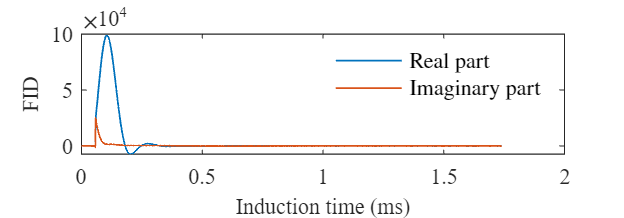

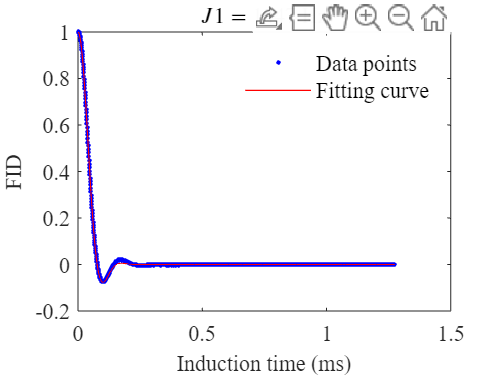

        figure(2);
        h = plot( fitresult, xData, yData );
        legend('Data points','Fitting curve','box','off')
        title(['$J1=',num2str(round(J1,0)),'$ Hz'],'interpreter','latex')
        xlabel( 'Induction time (ms)', 'Interpreter', 'none' );
        ylabel( 'FID', 'Interpreter', 'none' );
        fontsize(gcf,10,"points")
        fontname(gcf,'Times New Roman')
        set(gcf,'unit','centimeters','position',[10,10,8,6]);

       ii=ii+1;
    end
end

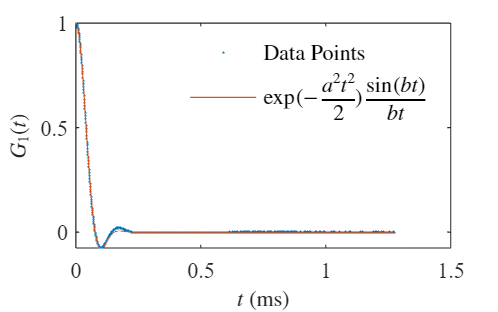

figure()
[xData, yData] = prepareCurveData( tt', y );
plot(xData, yData,'.','markersize',2)
hold on 
plot(xData,fitresult(xData),'-','linewidth',0.5)
legend('Data Points','$\exp(-\frac{a^2t^2}{2})\frac{\sin(bt)}{bt}$','interpreter','latex','box','off')
% title(['$a=',num2str(round(J1,0)),'$'],'interpreter','latex')
% 为坐标区加标签
xlabel( '$t$ (ms)', 'Interpreter', 'latex' );
ylabel( '$G_1(t)$', 'Interpreter', 'latex' );
fontsize(gcf,10,"points")
fontname(gcf,'Times New Roman')
set(gcf,'unit','centimeters','position',[10,10,8,5]);

Display the noise from the end range of the FID 

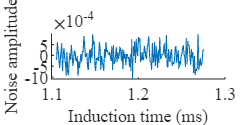

figure()
plot(xData(end-200:end), yData(end-200:end))
xlabel('Induction time (ms)')
ylabel('Noise amplitude')
fontsize(gcf,8,"points")
fontname(gcf,'Times New Roman')
set(gcf,'unit','centimeters','position',[10,10,4,2]);
set(gca,'box','off')

noise_std=var(yData(end-200:end))^0.5

noise_std = 4.2708e-04

Draw all the FID when varying the echo time

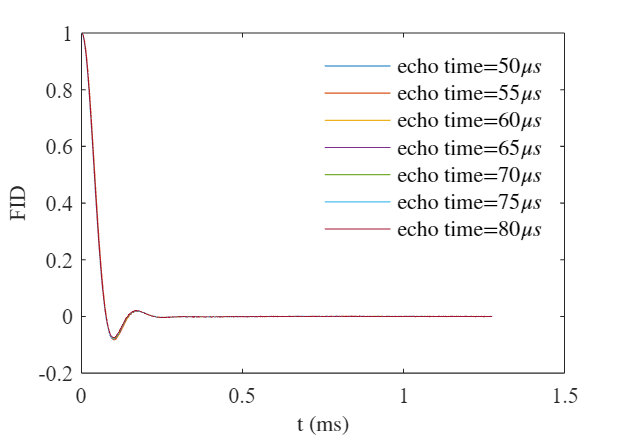

figure()
y=fid(:,1:7);
plot(tt,y./y(1,:))
% plot(t,fid)
hold on
xlabel('t (ms)','Interpreter','latex')
ylabel('FID')
legend(['echo time=$',num2str(echo_time_seq(num_seq(1))),'\mu s$'],['echo time=$',num2str(echo_time_seq(num_seq(2))),'\mu s$'],...
    ['echo time=$',num2str(echo_time_seq(num_seq(3))),'\mu s$'],['echo time=$',num2str(echo_time_seq(num_seq(4))),'\mu s$'], ...
    ['echo time=$',num2str(echo_time_seq(num_seq(5))),'\mu s$'],['echo time=$',num2str(echo_time_seq(num_seq(6))),'\mu s$'], ...
    ['echo time=$',num2str(echo_time_seq(num_seq(7))),'\mu s$'],...
    'interpreter','latex','box','off')
fontsize(gcf,10,"points")
fontname(gcf,'Times New Roman')
set(gcf,'unit','centimeters','position',[10,10,10,7]);

Display the distribution of extracted values of J, when varying the solid echo time and conducting repetitive experiments.

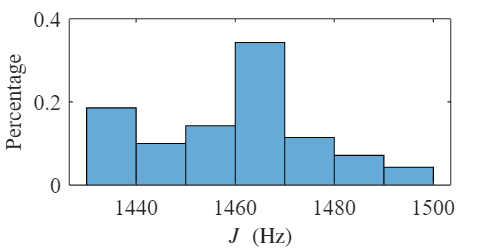

figure()
histogram(J1_seq(:,:),'binwidth',10,'Normalization','probability')
xlabel('$J\ (\mathrm{Hz})$','Interpreter','latex')
ylabel('Percentage')
fontsize(gcf,10,"points")
set(gcf,'unit','centimeters','position',[10,10,8,4]); 
fontname(gcf,"Times New Roman")